# Waypoints data processing

### Import .mat file

Clear the Matlab workspace of all values.

clear;clc

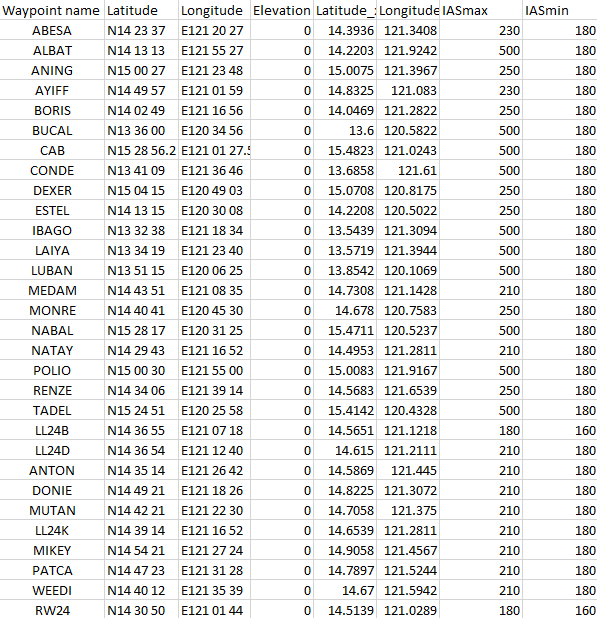

This tabulated data is an excel file converted into .mat format. This contains all relevant information regarding the waypoint. Note that this waypoints are in degrees, minutes, and seconds (DMS) and Matlab only accepts decimal degrees (DD) inputs. DMS must be externally converted into DD format. Other information includes the minimum and maximum indicated air speed (IAS) in knots.

WP = importdata("Waypoints_data_table.mat");

### Convert latitude and longitude into cartesian

Set the reference point as *origin* in the coordinates of RNW 24.

origin = [WP.Latitude_x(30), WP.Longitude_y(30), WP.Elevation(30)];

Use the *latlon2local() *function to convert the DD coordinates into cartesian coordinates with respect to the reference point. Create a table *wp_main *containing the converted data as well as the other data from the parent file.

[WP_x,WP_y,~] = latlon2local(WP.Latitude_x,WP.Longitude_y,WP.Elevation,origin);
wp_main = table(WP.WaypointName, WP_x, WP_y, WP.Elevation, WP.IASmax,WP.IASmin,'VariableNames', {'WP_name', 'Latitude_x', 'Longitude_y', 'Elevation', 'IASmax','IASmin'});

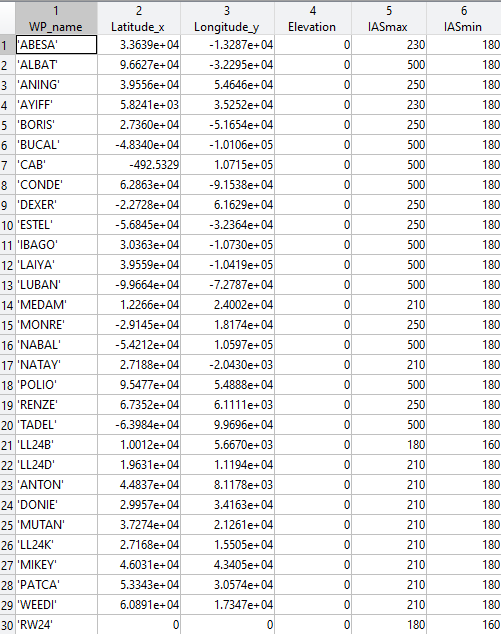

Create a new table trimming of the string data corresponding to the name of the waypoint. Convert the minimum and maximum IAS per waypoint to meters per second.

wp = table(WP_x, WP_y, WP.Elevation, WP.IASmax,WP.IASmin,'VariableNames', {'Latitude_x', 'Longitude_y', 'Elevation', 'IASmax','IASmin'});
% Conversion from knots to m/s
wp(:,4) = wp(:,4).*0.514444;
wp(:,5) = wp(:,5).*0.514444;      

### Creating routes

Encode into the variable *route_detail* the sequence of waypoints per route. There are 10 possible entry points with 3 variations having a total of 30 possible routes.

route_detail = [
    6,  10,  15,   4,  22,  30,  30,  30;       %BUCAL 3P -
    6,  10,  15,   4,  14,  24,  25,  30;       %BUCAL 5P 
    6,  10,  15,   4,  14,  27,  28,  30;       %BUCAL 7P 
    13, 10,  15,   4,  22,  30,  30,  30;       %LUBAN 3P 
    13, 10,  15,   4,  14,  24,  25,  30;       %LUBAN 5P 
    13, 10,  15,   4,  14,  27,  28,  30;       %LUBAN 7P
    20,  9,   4,  22,  30,  30,  30,  30;       %TADEL 3P 
    20,  9,   4,  14,  24,  25,  30,  30;       %TADEL 5P 
    20,  9,   4,  14,  27,  28,  30,  30;       %TADEL 7P
    16,  9,   4,  22,  30,  30,  30,  30;       %NABAL 3P 
    16,  9,   4,  14,  24,  25,  30,  30;       %NABAL 5P 
    16,  9,   4,  14,  27,  28,  30,  30;       %NABAL 7P
    7,   3,   4,  22,  30,  30,  30,  30;       %CAB 3P 
    7,   3,   4,  14,  24,  25,  30,  30;       %CAB 5P 
    7,   3,   4,  14,  27,  28,  30,  30;       %CAB 7P
    18,  3,   4,  22,  30,  30,  30,  30;       %POLIO 3P 
    18,  3,   4,  14,  24,  25,  30,  30;       %POLIO 5P 
    18,  3,   4,  14,  27,  28,  30,  30;       %POLIO 7P
    2,  19,   1,  22,  30,  30,  30,  30;       %ALBAT 3P 
    2,  19,   1,  17,  23,  25,  30,  30;       %ALBAT 5P 
    2,  19,   1,  17,  29,  28,  30,  30;       %ALBAT 7P
    8,   5,   1,  22,  30,  30,  30,  30;       %CONDE 3P 
    8,   5,   1,  17,  23,  25,  30,  30;       %CONDE 5P 
    8,   5,   1,  17,  29,  28,  30,  30;       %CONDE 7P
    12,  5,   1,  22,  30,  30,  30,  30;       %LAIYA 3P 
    12,  5,   1,  17,  23,  25,  30,  30;       %LAIYA 5P 
    12,  5,   1,  17,  29,  28,  30,  30;       %LAIYA 7P
    11,  5,   1,  22,  30,  30,  30,  30;       %IBAGO 3P 
    11,  5,   1,  17,  23,  25,  30,  30;       %IBAGO 5P 
    11,  5,   1,  17,  29,  28,  30,  30;]';    %IBAGO 7P

Store the information per route from *Route1 *to *Route30. *Retain the previous data per waypoint adding a waypoint number for each route. The sequencing of the route corresponds to the order of listed routes in *route_detail*.

for i = 1:width(route_detail)                  %30 column
    for j = 1:size(route_detail,1)             %13 row
        eval(['Route', num2str(i), '(:,1) =  route_detail(:,i);']);                   % 1st column = waypoint#
        eval(['Route', num2str(i), '(j,2) =  wp.Latitude_x(route_detail(j,i),1);']);  % 2nd column = lat of waypoint
        eval(['Route', num2str(i), '(j,3) =  wp.Longitude_y(route_detail(j,i),1);']); % 2nd column = long of waypoint
        eval(['Route', num2str(i), '(j,4) =  wp.Elevation(route_detail(j,i),1);']);   % 3rd column = elv of waypoint
        eval(['Route', num2str(i), '(j,5) =  wp.IASmax(route_detail(j,i),1);']);      % 4th column = max IAS at waypoint
        eval(['Route', num2str(i), '(j,6) =  wp.IASmin(route_detail(j,i),1);']) ;     % 5th column = min IAS at waypoint
    end 
end

### Route generation

In each route, interpolate the coordinates to have an increment of 2.5 nautical miles. This would serve as the locations where the IAS of each flight could be updated. Assign the interpolated coordinates into the variable *ITPpoints*. Retain the data for the minimum and maximum IAS per waypoint. Store each route in nested cell *Routes_ITP. *The order of sequence corresponds to the order of *route_detail.*

increment = 1852*2.5;                % 2.5nm to meters
Routes_ITP = cell(1, 30);

for i = 1:length(route_detail)
    ITPpoints = [];
    route_eval = eval(['Route' num2str(i)]);
    
    x = route_eval(:, 2);
    y = route_eval(:, 3);
    IASmax = route_eval(:, 5);
    IASmin = route_eval(:, 6);
    
    for j = 1:(length(x) - 1)
        x1 = x(j);
        y1 = y(j);
        x2 = x(j + 1);
        y2 = y(j + 1);
        
        distance = sqrt((x2-x1)^2 + (y2-y1)^2);
        disPoints = floor(distance / increment);
        
        xITP = linspace(x1, x2, disPoints + 1)';    % col 1 -- x-coordinates of Routes 
        yITP = linspace(y1, y2, disPoints + 1)';    % col 2 -- y-coordinates of Routes
        
        IASmaxITP = IASmax(j) * ones(size(xITP));   % col 3 -- IASmax of Routes
        IASminITP = IASmin(j) * ones(size(xITP));   % col 5 -- IASmin of Routes
        
        ITPpoints = [ITPpoints; [xITP, yITP, IASmaxITP, IASminITP]];      % Resulting cell per route per loop
    end
    
    Routes_ITP{i} = ITPpoints;                                                % Nested loop containing route per column
end

Given that each route differs in the numbers of waypoints to be used, the dimensionality would mismatch.

Find the route with the largest size and initialize a variable *Routefill* with 4 columns having the x and y coordinates in the first two columns and the minimum and maximum IAS for the remaining columns.

Create the variable *Routes* to be a nested cell containing all relevant data per route. Save this variable as *Route.mat*.

n = 0;
for i = 1:numel(Routes_ITP)
    current_n = size(Routes_ITP{i}, 1);
    n = max(n, current_n);
end    

% Define the dimensions
[width_Routes, length_Routes] = size(Routes_ITP);
[~, length_ITPpoints] = size(ITPpoints);

Routes = cell(width_Routes, length_Routes);
for i = 1:width_Routes
    for j = 1:length_Routes
        Routes{i, j} = zeros(n, length_ITPpoints);
    end
end

for i = 1:width_Routes
    for j = 1:length_Routes
        [width_specific, length_specific] = size(Routes_ITP{i,j});
        specificRoute = Routes_ITP{i,j};
        Routefill = Routes{i,j};
        for ii = 1:length_specific
            for jj = 1:width_specific
                Routefill(jj,ii) = specificRoute(jj,ii);
            end
        end
        Routes{i,j} = Routefill;
    end
end

for i = 1:width_Routes
    for j = 1:length_Routes
        Routes{i,j} = num2cell(Routes{i,j});
    end
end


save('Routes.mat', 'Routes');

### Visualization

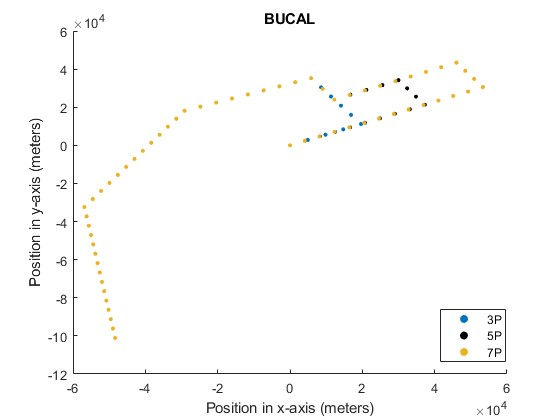

Use a scatter plot to plot the routes. 

As an example, the code above calls for the route *BUCAL 3P, BUCAL 5P, *and *BUCAL 7P* to be plotted.

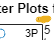

for i = 1:width_Routes
    for j = 1:length_Routes
        Routes{i,j} = cell2mat(Routes{i,j});
    end
end

flight = 1;
xx = 3*flight;
x1 = Routes{xx-2}(:, 1);
y1 = Routes{xx-2}(:, 2);
x2 = Routes{xx-1}(:, 1);
y2 = Routes{xx-1}(:, 2);
x3 = Routes{xx}(:, 1);
y3 = Routes{xx}(:, 2);

figure;
scatter(x1, y1, 10,"filled");
hold on;
scatter(x2, y2, 10,"filled","k");
scatter(x3, y3, 10,"filled");
hold off;
title('BUCAL');
legend('3P','5P','7P')
xlabel('Position in x-axis (meters)');
ylabel('Position in y-axis (meters)');

legend("Position", [0.78631,0.14153,0.11786,0.11905])